# Learning a CNN model

Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;
inputSize = [349, 150, 2];

inputSpecgramsFile = 'Spectrograms\specgrams-all-lin_lr.h5';

timeValues = h5read(inputSpecgramsFile, '/axis/time');
freqValues = h5read(inputSpecgramsFile, '/axis/freq');

f = figure('Position', [0, 0, 800 1100])

f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 1100]
       Units: 'pixels'

  Show all properties


opt = {[0.02 0.00], [0.1 0.1], [0.1 0.01]};
subplot = @(m,n,p) subtightplot(m,n,p,opt{:});

Display average score maps by label

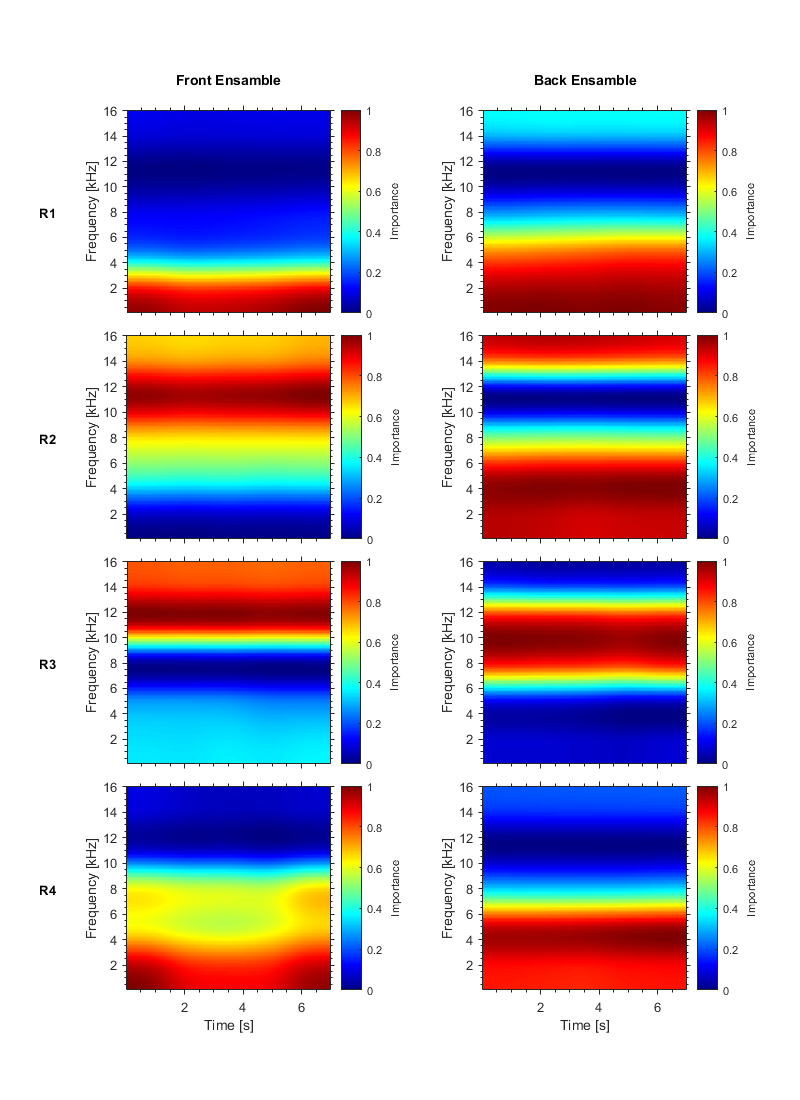

scoreMapsSum = zeros([349 150 2]);
% imageNames = {'Front', 'Back'};
%  
% figure('Position', [0 0 1000 400 * 4])   
% [ha, pos] = tight_subplot(4,2,[.05 .05],[.05 .03],[.05 .05]);
% 
% for iNetwork = 1:4    
%     for ii = 1:2
% %         subplot(4, 2, );
%         axes(ha((iNetwork - 1) * 2 + ii));
%         
%         
%         colormap jet; 
%         axis xy;  
%         pbaspect([1 1 1]);
%         
%         if iNetwork == 1
%             title(imageNames{ii});
%         end
%         
%         if iNetwork == 4
%             xlabel('Time [s]');
%         end
%         ylabel('Frequency [kHz]');
%         ylabel(colorbar, 'Importance');
%     	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
%         
%     end
% %     sgtitle(sprintf('Average Grad-CAM Score Map (Model No. %d)', iNetwork));
% end

mapNames = {'Front Ensamble', 'Back Ensamble'};

for iNetwork = 1:4    
    for iMap = 1:2
    	subplot(4, 2, 2*(iNetwork-1) + iMap)
        
    	load(sprintf('gam/gradCAM_meanScoreMap_pn%d_%d', iMap, iNetwork), 'meanScoreMap');
        scoreMapsSum(:, :, iMap) = scoreMapsSum(:, :, iMap) + meanScoreMap;    
            
    	imagesc(timeValues, freqValues / 1000, rescale(meanScoreMap)');
    	colormap jet; axis xy; pbaspect([1 1 1]);
        if iNetwork == 1
    	    title({mapNames{iMap}, ''})
        end
        
        if iNetwork == 4
    	    xlabel('Time [s]')	   
        else
            set(gca,'XTickLabel',[])
        end
        ylabel('Frequency [kHz]')
    	ylabel(colorbar, 'Importance')
    	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
        
        if iMap == 1
            text(-3, 8, ['R' num2str(iNetwork)], 'FontWeight', 'bold');
        end
    end
end
savegraphb(f, 'gradCAM_1234');

f = figure('Position', [0, 0, 800 1100])

f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 800 1100]
       Units: 'pixels'

  Show all properties


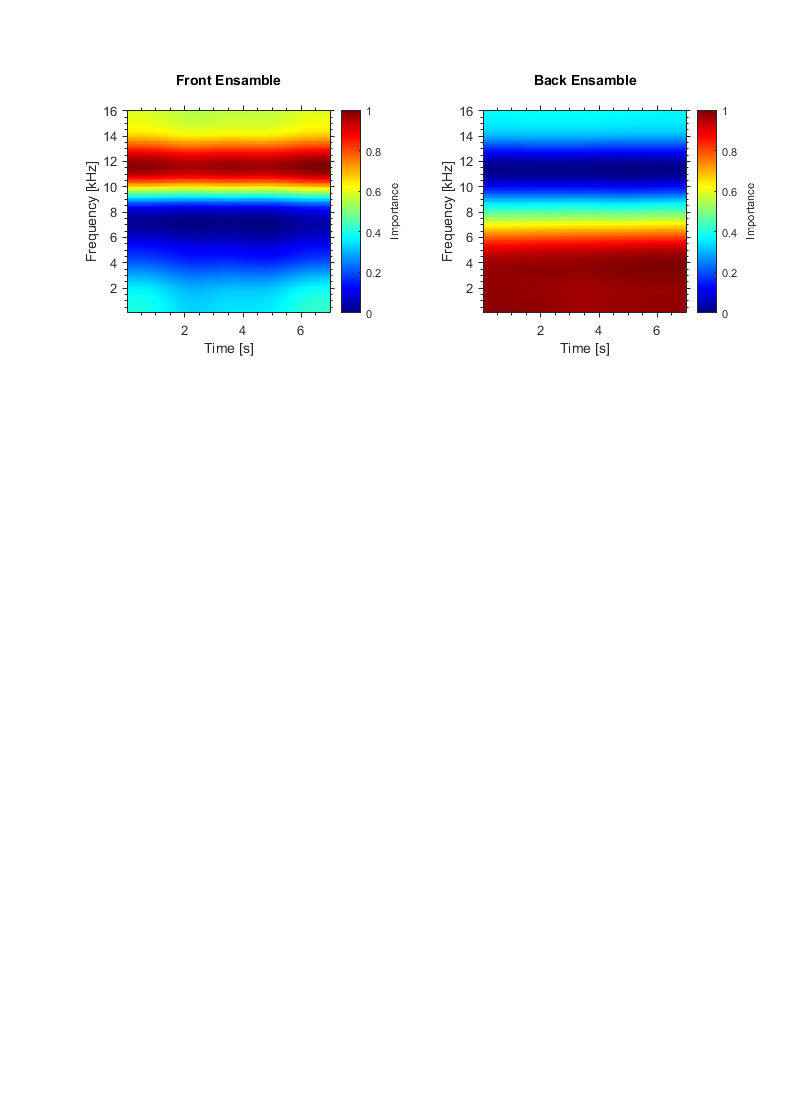

for iMap = 1:2
	subplot(4, 2, iMap)
        
	imagesc(timeValues, freqValues / 1000, rescale(scoreMapsSum(:, :, iMap))');
	colormap jet; axis xy; pbaspect([1 1 1]);
	title({mapNames{iMap}, ''})
    
	xlabel('Time [s]')	   
    ylabel('Frequency [kHz]')
	ylabel(colorbar, 'Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
end
savegraphb(f, 'gradCAM_all');

function cam = customGradCam(currentNetwork, input, label)
    cam = gradCAM(currentNetwork, input, label,... 
        'FeatureLayer', 'relu_5');
end
